clc;
clear all;
% dataActual=table();
% for i= 2:29
    m=load('loaddata.m');
    l=load('linedata.m');
%     data=m(i,2)+120;
%     m(i,2)= data;
    [voltage,R,X,P,Q,Ibr]= indLoadFlow(m,l);
%     if i == 2
%         dataActual.Pentration2= voltage
%     else
%          name = "Pentration at "+ num2str(i)
%         dataActual.(name)= voltage;
%     end
    
% end
% names= strings(1, 29);
% for q= 1:29
% names(1,q)="Bus "+num2str(q);
% end
% dataActual.Properties.RowNames=names;
% writetable(dataActual,'voltageProfile.xlsx','WriteRowNames',true)

no = length(m);  % number of buses
br = length(l);  % number of branches
max_harmonic = 13;  % maximum harmonic order to analyze
max_iter = 20;  % maximum number of iterations for each harmonic
tolerance = 1e-6;  % convergence tolerance
vb=voltage;

% Define EV charger parameters
ev_chargers = struct('bus', {}, 'power', {}, 'pf', {}, 'efficiency', {}, 'spectrum', {});
ev_chargers(1).bus = 5;  % Example: EV charger at bus 5
ev_chargers(1).power = 0.05;  % 50 kW in p.u. (assuming 100 MVA base)
ev_chargers(1).pf = 0.98;
ev_chargers(1).efficiency = 0.95;
ev_chargers(1).spectrum = [
    1, 1.00, 0;    % Fundamental
    5, 0.20, 0;    % 5th harmonic
    7, 0.14, 0;    % 7th harmonic
    11, 0.09, 0;   % 11th harmonic
    13, 0.08, 0;   % 13th harmonic
];

% Initialize harmonic voltages and currents
V_harm = zeros(no, max_harmonic);
I_harm = zeros(br, max_harmonic);

% Perform harmonic analysis
for h = 1:max_harmonic
    % Initialize voltages for this harmonic
    V_h = ones(no, 1);
    
    for iter = 1:max_iter
        % Backward sweep
        I_h = calculate_harmonic_currents(V_h, h, ev_chargers, l, R, X, P, Q);
        
        % Forward sweep
        V_h_new = forward_sweep(V_h, I_h, l, R, X, h);
        
        % Check convergence
        if max(abs(V_h_new - V_h)) < tolerance
            break;
        end
        
        V_h = V_h_new;
    end
    
    % Store results for this harmonic
    V_harm(:, h) = V_h;
    I_harm(:, h) = I_h;
    
    % Diagnostic: Print max magnitude for this harmonic
    disp(['Max magnitude for harmonic ', num2str(h), ': ', num2str(max(abs(V_h)))]);
end

br = 28

I_fund = 0.0526

br = 28

I_fund = 0.0536

br = 28

I_fund = 0.0537

br = 28

I_fund = 0.0537

br = 28

I_fund = 0.0537

Max magnitude for harmonic 1: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 2: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 3: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 4: 1


br = 28

I_fund = 0.0526

br = 28

I_fund = 0.0527

br = 28

I_fund = 0.0527

Max magnitude for harmonic 5: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 6: 1


br = 28

I_fund = 0.0526

br = 28

I_fund = 0.0527

br = 28

I_fund = 0.0527

Max magnitude for harmonic 7: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 8: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 9: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 10: 1


br = 28

I_fund = 0.0526

br = 28

I_fund = 0.0527

br = 28

I_fund = 0.0527

Max magnitude for harmonic 11: 1


br = 28

I_fund = 0.0526

Max magnitude for harmonic 12: 1


br = 28

I_fund = 0.0526

br = 28

I_fund = 0.0527

br = 28

I_fund = 0.0527

Max magnitude for harmonic 13: 1



 % Diagnostic: Print max magnitude for this harmonic
    disp(['Max magnitude for harmonic ', num2str(h), ': ', num2str(max(abs(V_h)))]);

Max magnitude for harmonic 13: 1




% Diagnostic: Print magnitudes of harmonics for a specific bus (e.g., bus 5)
disp('Harmonic magnitudes at bus 5:');

Harmonic magnitudes at bus 5:


disp(abs(V_harm(5,:)));

  Columns 1 through 4

    0.9807    1.0000    1.0000    1.0000

  Columns 5 through 8

    0.9989    1.0000    0.9993    1.0000

  Columns 9 through 12

    1.0000    1.0000    0.9995    1.0000

  Column 13

    0.9996




% Post-processing and analysis
% Modified THD calculation
THD_V = calculate_thd(V_harm(:,1), V_harm);
THD_I = calculate_thd(I_harm(:,1), I_harm);

% Diagnostic: Print THD calculation details for a specific bus (e.g., bus 5)
fundamental_v = abs(V_harm(5,1));
harmonic_sum_v = sum(abs(V_harm(5,2:end)).^2);
thd_v_check = sqrt(harmonic_sum_v) / fundamental_v * 100;
disp(['THD calculation check for bus 5:']);

THD calculation check for bus 5:


disp(['Fundamental magnitude: ', num2str(fundamental_v)]);

Fundamental magnitude: 0.98067


disp(['Sum of squared harmonics: ', num2str(harmonic_sum_v)]);

Sum of squared harmonics: 11.9947


disp(['Calculated THD: ', num2str(thd_v_check), '%']);

Calculated THD: 353.159%



% Display results
disp('Voltage THD (%):');

Voltage THD (%):


disp(THD_V);

  346.4102
  349.4275
  350.2542
  351.8240
  353.1590
  360.5981
  361.0780
  361.7381
  365.1190
  365.4358
  366.4733
  367.8174
  368.3413
  368.5177
  349.4500
  353.5636
  353.5948
  362.1145
  362.2611
  362.5002
  362.5086
  367.3902
  367.4033
  367.9166
  368.0395
  368.6502
  368.6568
  368.9155
  368.9774



disp('Current THD (%):');

Current THD (%):


disp(THD_I);

         0
         0
         0
   53.8580
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



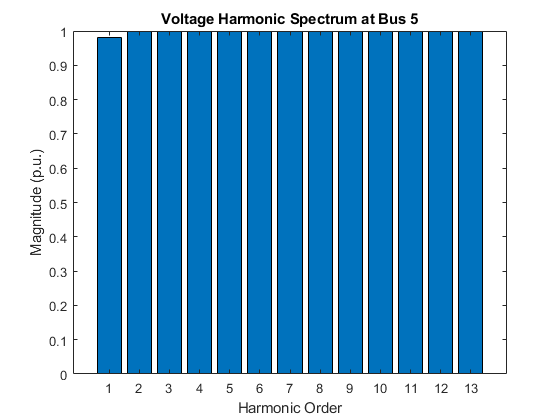


% Plot harmonic spectrum (example for bus 5)
figure;
bar(1:max_harmonic, abs(V_harm(5,:)));
title('Voltage Harmonic Spectrum at Bus 5');
xlabel('Harmonic Order');
ylabel('Magnitude (p.u.)');

function [voltageModify,R,X,P,Q,Ibr]= indLoadFlow(m,l)
format short;
br=length(l);
no=length(m);
f=0;
d=0;
MVAb=100;
KVb=11;
Zb=(KVb^2)/MVAb;
Pg = zeros(no,1);
Pg1 = zeros(no,1);
 
for i=1:br
    R(i,1)=(l(i,4))/Zb;
    X(i,1)=(l(i,5))/Zb;
end
for i=1:no
    P(i,1)=(m(i,2)/(1000*MVAb));
    Q(i,1)=(m(i,3)/(1000*MVAb));
end
R;
X;
P;
Q;

C=zeros(br,no);
for i=1:br
    a=l(i,2);
    b=l(i,3);
    for j=1:no
        if a==j
            C(i,j)=-1;
        end
        if b==j
            C(i,j)=1;
        end
    end
end
C;
e=1;
for i=1:no
    d=0;
    for j=1:br
        if C(j,i)==-1
            d=1;
        end
    end
    if d==0
        endnode(e,1)=i;
        e=e+1;
    end
end
endnode;
h=length(endnode);
for j=1:h
    e=2;
    
    f=endnode(j,1);
   % while (f~=1)
   for s=1:no
     if (f~=1)
       k=1;  
       for i=1:br
           if ((C(i,f)==1)&&(k==1))
                f=i;
                k=2;
           end
       end
       k=1;
       for i=1:no
           if ((C(f,i)==-1)&&(k==1));
                f=i;
                g(j,e)=i;
                e=e+1;
                k=3;
           end            
       end
     end
   end
end
for i=1:h
    g(i,1)=endnode(i,1);
end
g;
w=length(g(1,:));
for i=1:h
    j=1;
    for k=1:no 
        for t=1:w
            if g(i,t)==k
                g(i,t)=g(i,j);
                g(i,j)=k;
                j=j+1;
             end
         end
    end
end
g;
for k=1:br
    e=1;
    for i=1:h
        for j=1:w-1
            if (g(i,j)==k) 
                if g(i,j+1)~=0
                    adjb(k,e)=g(i,j+1);            
                    e=e+1;
                else
                    adjb(k,1)=0;
                end
             end
        end
    end
end
adjb;
for i=1:br-1
    for j=h:-1:1
        for k=j:-1:2
            if adjb(i,j)==adjb(i,k-1)
                adjb(i,j)=0;
            end
        end
    end
end
adjb;
x=length(adjb(:,1));
ab=length(adjb(1,:));
for i=1:x
    for j=1:ab
        if adjb(i,j)==0 && j~=ab
            if adjb(i,j+1)~=0
                adjb(i,j)=adjb(i,j+1);
                adjb(i,j+1)=0;
            end
        end
        if adjb(i,j)~=0
            adjb(i,j)=adjb(i,j)-1;
        end
    end
end
adjb;
for i=1:x-1
    for j=1:ab
        adjcb(i,j)=adjb(i+1,j);
    end
end
b=length(adjcb);

% voltage current program

for i=1:no
    vb(i,1)=1;
end
for s=1:10
for i=1:no
    nlc(i,1)=conj(complex(P(i,1),Q(i,1)))/(vb(i,1));
end
nlc;
for i=1:br
    Ibr(i,1)=nlc(i+1,1);
end
Ibr;
xy=length(adjcb(1,:));
for i=br-1:-1:1
    for k=1:xy
        if adjcb(i,k)~=0
            u=adjcb(i,k);
            Ibr(i,1)=Ibr(i,1)+Ibr(u,1);
        end
    end      
end
Ibr;
for i=2:no
      g=0;
      for a=1:b 
          if xy>1
            if adjcb(a,2)==i-1 
                u=adjcb(a,1);
                vb(i,1)=((vb(u,1))-((Ibr(i-1,1))*(complex((R(i-1,1)),X(i-1,1)))));
                g=1;
            end
            if adjcb(a,3)==i-1 
                u=adjcb(a,1);
                vb(i,1)=((vb(u,1))-((Ibr(i-1,1))*(complex((R(i-1,1)),X(i-1,1)))));
                g=1;
            end
          end
        end
        if g==0
            vb(i,1)=((vb(i-1,1))-((Ibr(i-1,1))*(complex((R(i-1,1)),X(i-1,1)))));
        end
end
s=s+1;
end
nlc;
Ibr;
vb;
vbp=[abs(vb)];

for i=1:no
    va(i,2)=vbp(i,1);
end
for i=1:no
    va(i,1)=i;
    P1(i) = P(i);
    Q1(i) = Q(i);
end

va;
Ibrp=[abs(Ibr)];
PL(1,1)=0;
QL(1,1)=0;

% losses at base case 
for f=1:br
    Pl(f,1)=(Ibrp(f,1)^2)*R(f,1);
    Ql(f,1)=X(f,1)*(Ibrp(f,1)^2);
    PL(1,1)=PL(1,1)+Pl(f,1);
    QL(1,1)=QL(1,1)+Ql(f,1);
end

Plosskw=(Pl)*100000;
Qlosskw=(Ql)*100000;
PL=(PL)*100000;
QL=(QL)*100000;

voltage = vbp(:,1);

v_mag = va(:,2);
voltageModify=v_mag;
end
% Helper functions



function I_h = calculate_harmonic_currents(V_h, h, ev_chargers, linedata, R, X, P, Q)
    br = size(linedata, 1)
    I_h = zeros(br, 1);
    
    % Calculate harmonic current injections from EV chargers
    I_inj_h = zeros(size(V_h));
    for charger = ev_chargers
        I_fund = (charger.power / charger.efficiency) / abs(V_h(charger.bus))
        I_fund = I_fund * (cos(acos(charger.pf)) - 1j*sin(acos(charger.pf)));
        
        h_data = charger.spectrum(charger.spectrum(:,1) == h, :);
        if ~isempty(h_data)
            magnitude = h_data(2) * abs(I_fund);
            phase = h_data(3);
            I_inj_h(charger.bus) = I_inj_h(charger.bus) + magnitude * exp(1j * deg2rad(phase));
        end
    end
    
    % Backward sweep to calculate branch currents
    for i = br:-1:1
        from_bus = linedata(i, 2);
        to_bus = linedata(i, 3);
        
        if h == 1
            % For fundamental frequency, include normal loads
            S_load = complex(P(to_bus), Q(to_bus));
            I_load = conj(S_load / V_h(to_bus));
        else
            % For harmonics, only consider harmonic injections
            I_load = I_inj_h(to_bus);
        end
        
        I_h(i) = I_load;
        
        % Add current from downstream branches
        for j = 1:br
            if linedata(j, 2) == to_bus
                I_h(i) = I_h(i) + I_h(j);
            end
        end
        if h > 1  % For harmonics only
        I_inj_h(from_bus) = I_inj_h(from_bus) - I_h(i);
    end
    end
end

function V_h_new = forward_sweep(V_h, I_h, linedata, R, X, h)
    no = length(V_h);
    V_h_new = zeros(no, 1);
    V_h_new(1) = 1;  % Assume slack bus voltage is 1∠0° for all harmonics
    
    for i = 1:size(linedata, 1)
        from_bus = linedata(i, 2);
        to_bus = linedata(i, 3);
        Z_h = complex(R(i), h*X(i));
        V_h_new(to_bus) = V_h_new(from_bus) - Z_h * I_h(i);
    end
end

function THD = calculate_thd(fundamental, harmonics)
    THD = sqrt(sum(abs(harmonics(:,2:end)).^2, 2)) ./ abs(fundamental) * 100;
end
